# Multiple Trial SimulationsTest File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 26/10/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Add path to backtestedPortfolio object: 

addpath '/Users/Ninamatthews/Documents/MATLAB/STA5000W DISSERTATION Code/OOP'

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

# TEST CASE: 5 data points per hyper-parameter

## 3. Set up hyper-parameter ranges (will generalise at a later stage)

Range is created for all hyper parameters that will be varied.

For the data tuning we use: 

- Cash Constriants

- Standard deviation range for Winsorised data

- Regularisation lambda

CC_range  = linspace(0, 1, 5);
W_sd_range  = linspace(1, 5, 5);
Lambda_reg_range = linspace(0, 1, 5);
hyperparameter_set = [CC_range; W_sd_range; Lambda_reg_range];

% Initialize an empty matrix to store configurations
num_configs = size(hyperparameter_set, 2)^size(hyperparameter_set, 1);
configurations = zeros(num_configs, size(hyperparameter_set, 1));

% Nested loops to generate all configurations based on the size of hyperparameter_set
col = 1;
for config1 = 1:size(hyperparameter_set, 2)
    for config2 = 1:size(hyperparameter_set, 2)
        for config3 = 1:size(hyperparameter_set, 2)
            % Store the current combination of values in the configurations matrix
            configurations(col, :) = [hyperparameter_set(1, config1); hyperparameter_set(2, config2); hyperparameter_set(3, config3)];
            col = col + 1;
        end
    end
end

## 4.  Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

### Default Model with no changes:

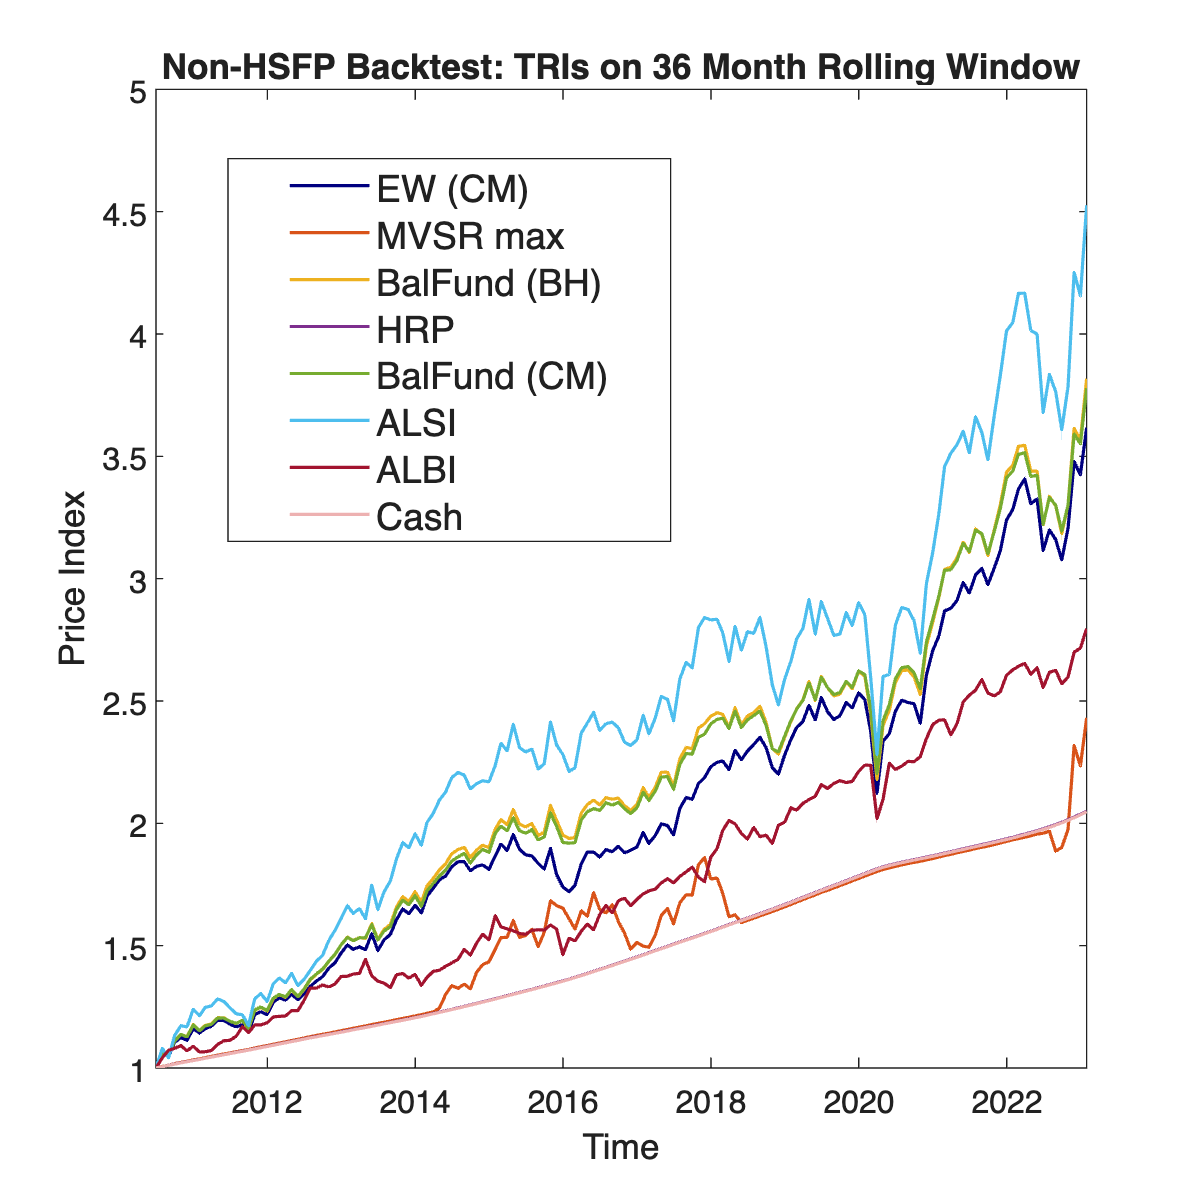

CC = 1; % no constraint if == 1
W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class1 = backtestedPortfolios;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'none';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class1.WinsorStd = W_sd;
test_class1.CashConstriant = CC;
test_class1.RegLambda = 0.00;

%%% Run backtest
test1_bcktest = OOPbacktest_analysis(test_class1);
%%% Plot performance Curves 
PerformancePlot(test1_bcktest);

## 5. Simulation Loop for changing hyper parameters

### 5.1 Test without parallisation 

profile on
data_processing_config_sim_cellArr = simulate_backtest(configurations,test_class1);
profile off

profile viewer

### 5.2 Using parellel computing

tic
TCpar_data_processing_config_sim_cellArr = para_simulate_backtest(configurations,test_class1);
toc

Elapsed time is 44.781773 seconds.


profile viewer

### 5.3 Checking the results are equivalent

isequal(data_processing_config_sim_cellArr,TCpar_data_processing_config_sim_cellArr)

ans = logical
   1


**SAVE Simulation Cell Array:**

sim_filename = ['DATA-SIM_TC-', num2str(num_configs), '_BKTST-PERFORMANCE-M-CELL_ARR.mat'];
save(fullfile(dataExportpath,sim_filename),'TCpar_data_processing_config_sim_cellArr');

## 6. TEST CASE: Visualisation of Simulations

load DATA-SIM_TC-125_BKTST-PERFORMANCE-M-CELL_ARR.mat

### 6.1 Visualise MV Simulations

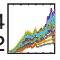

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(TCpar_data_processing_config_sim_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(TCpar_data_processing_config_sim_cellArr{i}.RollingPerformance.Time, TCpar_data_processing_config_sim_cellArr{i}.RollingPerformance.("MVSR max"));  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['Test Case MV Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 14);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

TC_MV_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

**Export TC MV Simulations plot**

exportName = 'TC_MV_BCKTST_SIM_Performance_plot.pdf';
exportgraphics(TC_MV_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 6.2 Visualise HRP Simulations

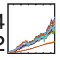

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(TCpar_data_processing_config_sim_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(TCpar_data_processing_config_sim_cellArr{i}.RollingPerformance.Time, TCpar_data_processing_config_sim_cellArr{i}.RollingPerformance.("HRP"));  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['Test Case HRP Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 14);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

TC_HRP_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

**Export TC MV Simulations plot**

exportName = 'TC_HRP_BCKTST_SIM_Performance_plot.pdf';
exportgraphics(TC_HRP_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',300);

# FULL SIMULATION: 

## 3. Set up hyper-parameter ranges (will generalise at a later stage)

Range is created for all hyper parameters that will be varied.

For the data tuning we use: 

- Cash Constriants

- Standard deviation range for Winsorised data

- Regularisation lambda

**15 Data points per hyper-parameter**

CC_range  = linspace(0, 1, 15);
W_sd_range  = linspace(1, 5, 15);
Lambda_reg_range = linspace(0, 1, 15);
hyperparameter_set = [CC_range; W_sd_range; Lambda_reg_range];

% Initialize an empty matrix to store configurations
num_configs = size(hyperparameter_set, 2)^size(hyperparameter_set, 1);
configurations = zeros(num_configs, size(hyperparameter_set, 1));

% Nested loops to generate all configurations based on the size of hyperparameter_set
col = 1;
for config1 = 1:size(hyperparameter_set, 2)
    for config2 = 1:size(hyperparameter_set, 2)
        for config3 = 1:size(hyperparameter_set, 2)
            % Store the current combination of values in the configurations matrix
            configurations(col, :) = [hyperparameter_set(1, config1); hyperparameter_set(2, config2); hyperparameter_set(3, config3)];
            col = col + 1;
        end
    end
end

### 6.1 Create inset for the HRP plot to explain the flat lines at the bottom:

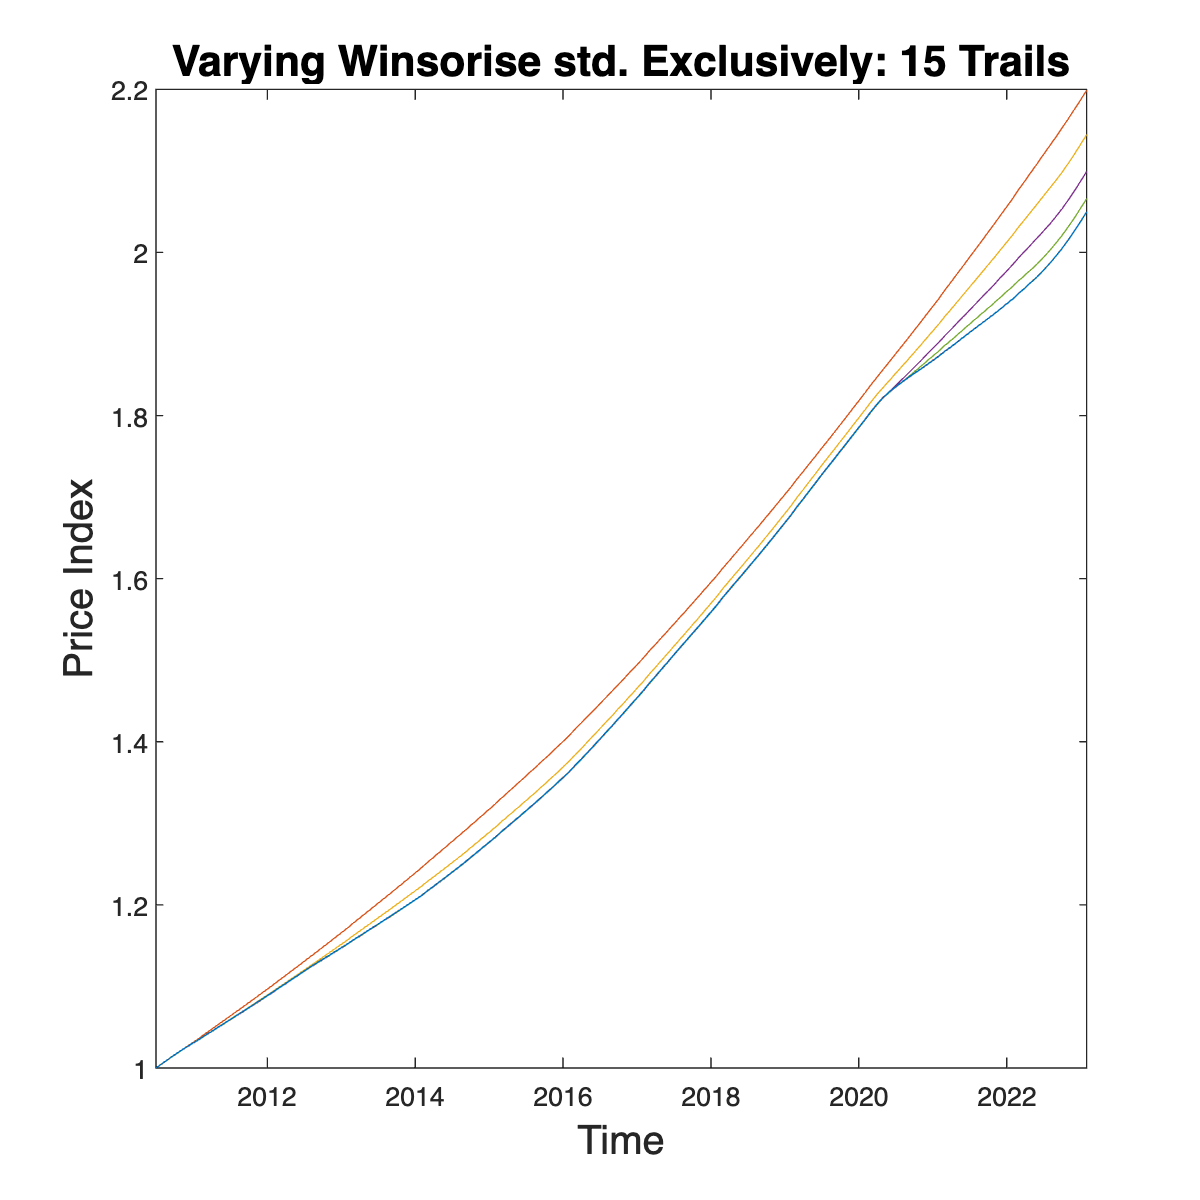

%%% Create storage for simulation objects
configurationMatrix  = linspace(0, 5, 15);
HRP_winsor_num_configs = length(configurationMatrix);
simulationCellArray = cell(1, HRP_winsor_num_configs);
%%% Create storage for the cummulative performance curves 
for config = 1:HRP_winsor_num_configs  
    % test_class1.CashConstriant = configurationMatrix(config);
    test_class1.WinsorStd = configurationMatrix(config);
    % test_class1.RegLambda = configurationMatrix(config);

    %%% Run backtest
    simulationCellArray{config} = OOPbacktest_analysis(test_class1); 
end

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(simulationCellArray)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(simulationCellArray{i}.RollingPerformance.Time, simulationCellArray{i}.RollingPerformance.("HRP"));  % Adjust VariableName1 as needed
    hold on;
    i;% Overlay plots on the same axes
end
% Customize the plot as needed
title(['Varying Winsorise std. Exclusively: ',num2str(HRP_winsor_num_configs), ' Trails'],'FontSize', 16);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

HRP_Winsor_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

**Export HRP winsorise std. Simulations plot**

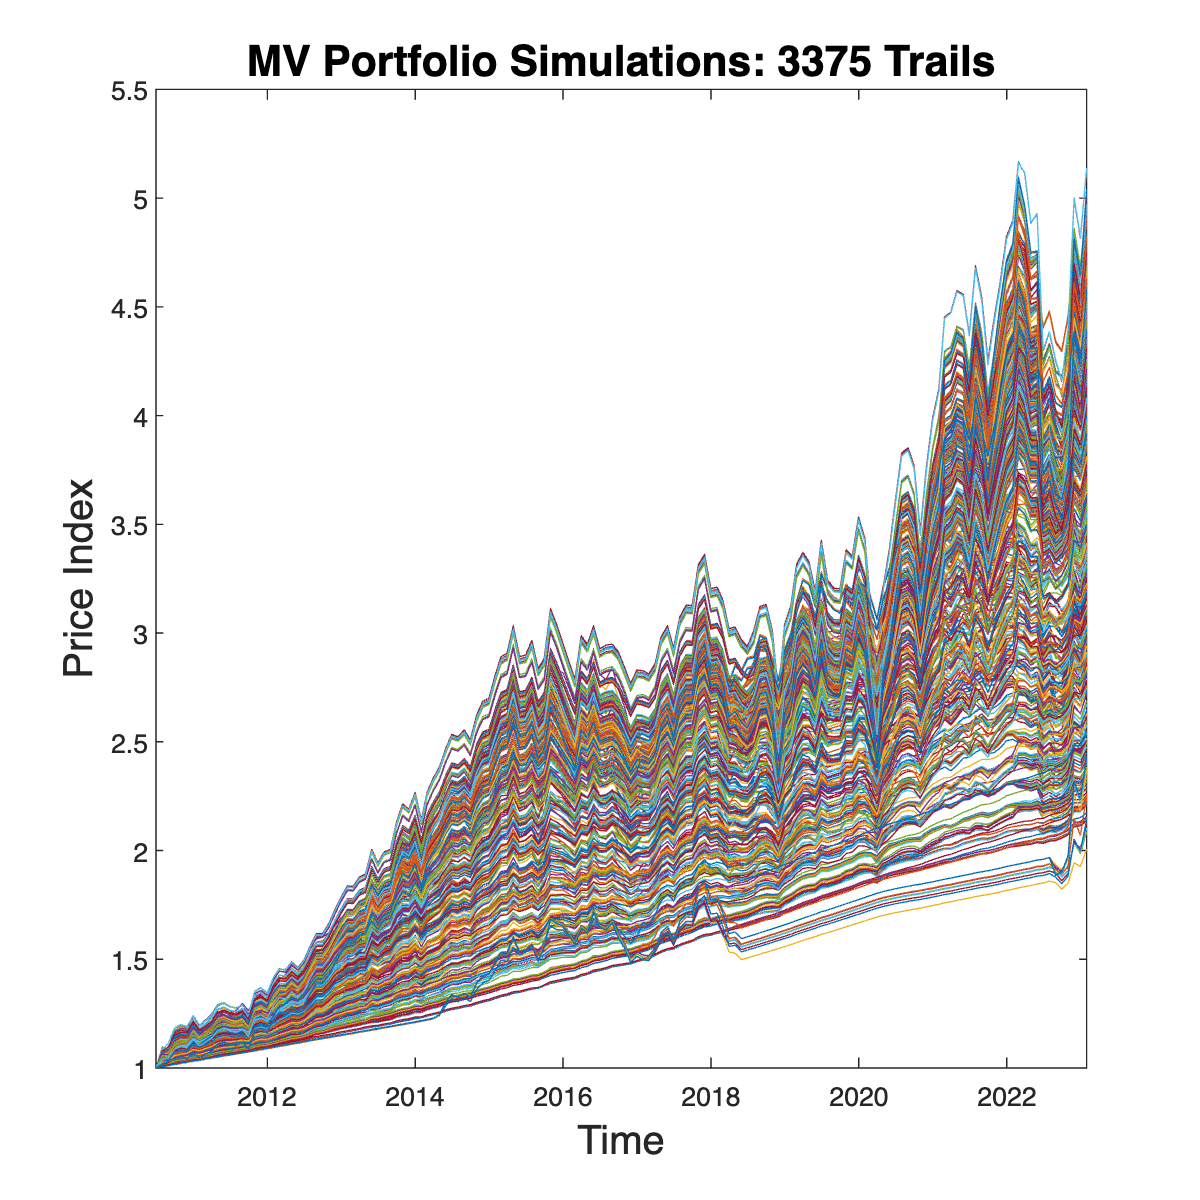

exportName = 'HRP_Winsor_BCKTST_SIM_Performance_plot.pdf';

exportgraphics(HRP_Winsor_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',500);

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it

for i = 1:numel(data_processing_config_sim_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(data_processing_config_sim_cellArr{i}.RollingPerformance.Time, data_processing_config_sim_cellArr{i}.RollingPerformance.("MVSR max"));  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['MV Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 16);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

HRP_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

**Export MV Simulations plot**

exportName = 'MV_BCKTST_SIM_Performance_plot.pdf';
exportgraphics(HRP_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',500);